# 2025.06.13 LCE-10 开关电源设计与测试

## Output Efficiency

data = [
% input V,I     output V,I
% TPS54331 (buck)
5.224, 0.046,   4.05,  0.050
5.190, 0.389,   3.81,  0.473
5.092, 1.378,   3.15,  1.578
% SX1308 (boost)
5.217, 0.220,   10.12, 0.049
5.122, 1.176,   9.87,  0.492
4.990, 2.410,   9.68,  0.967
];
efficiency = data(:, 3).*data(:, 4)./(data(:, 1).*data(:, 2))*100   % unit: percentage

efficiency =    84.2683
   89.2625
   70.8402
   43.2049
   80.6186
   77.8367


disp(num2str(efficiency, '%.2f'))

84.27
89.26
70.84
43.20
80.62
77.84


## Line Regulation

data0 = [
% input @ output      input @ output
4.887, 3.886,      6.317, 3.893   % TPS54331 (buck)
4.810, 10.099,     6.261, 10.093  % SX1308 (boost)
];
% line_regu = delta_out/delta_in
line_regu = (data0(:, 4) - data0(:, 2))./(data0(:, 3) - data0(:, 1))*1000   % unit: mV/V

line_regu =     4.8951
   -4.1351


disp(num2str(line_regu, '%.2f'))

 4.90
-4.14


## Load Regulation

% load_regu = delta_out/vout
% resi = - delta_out/delta_iout
data1 = data(1:3, [3 4]);
data2 = data(4:6, [3 4]);

% TPS54331 (buck)
TP_load_regu = diff(data1(:, 1))./data1(1:2, 1)*100;    % unit: %
TP_resi = - diff(data1(:, 1))./diff(data1(:, 2));         % unit: Ohm
round(TP_load_regu, 2)

ans =    -5.9300
  -17.3200


round(TP_resi, 2)

ans =     0.5700
    0.6000



% SX1308 (boost)
SX_load_regu = diff(data2(:, 1))./data2(1:2, 1)*100;    % unit: %
SX_resi = - diff(data2(:, 1))./diff(data2(:, 2));
round(SX_load_regu, 2)

ans =    -2.4700
   -1.9300


round(SX_resi, 2)

ans =     0.5600
    0.4000


## 作图

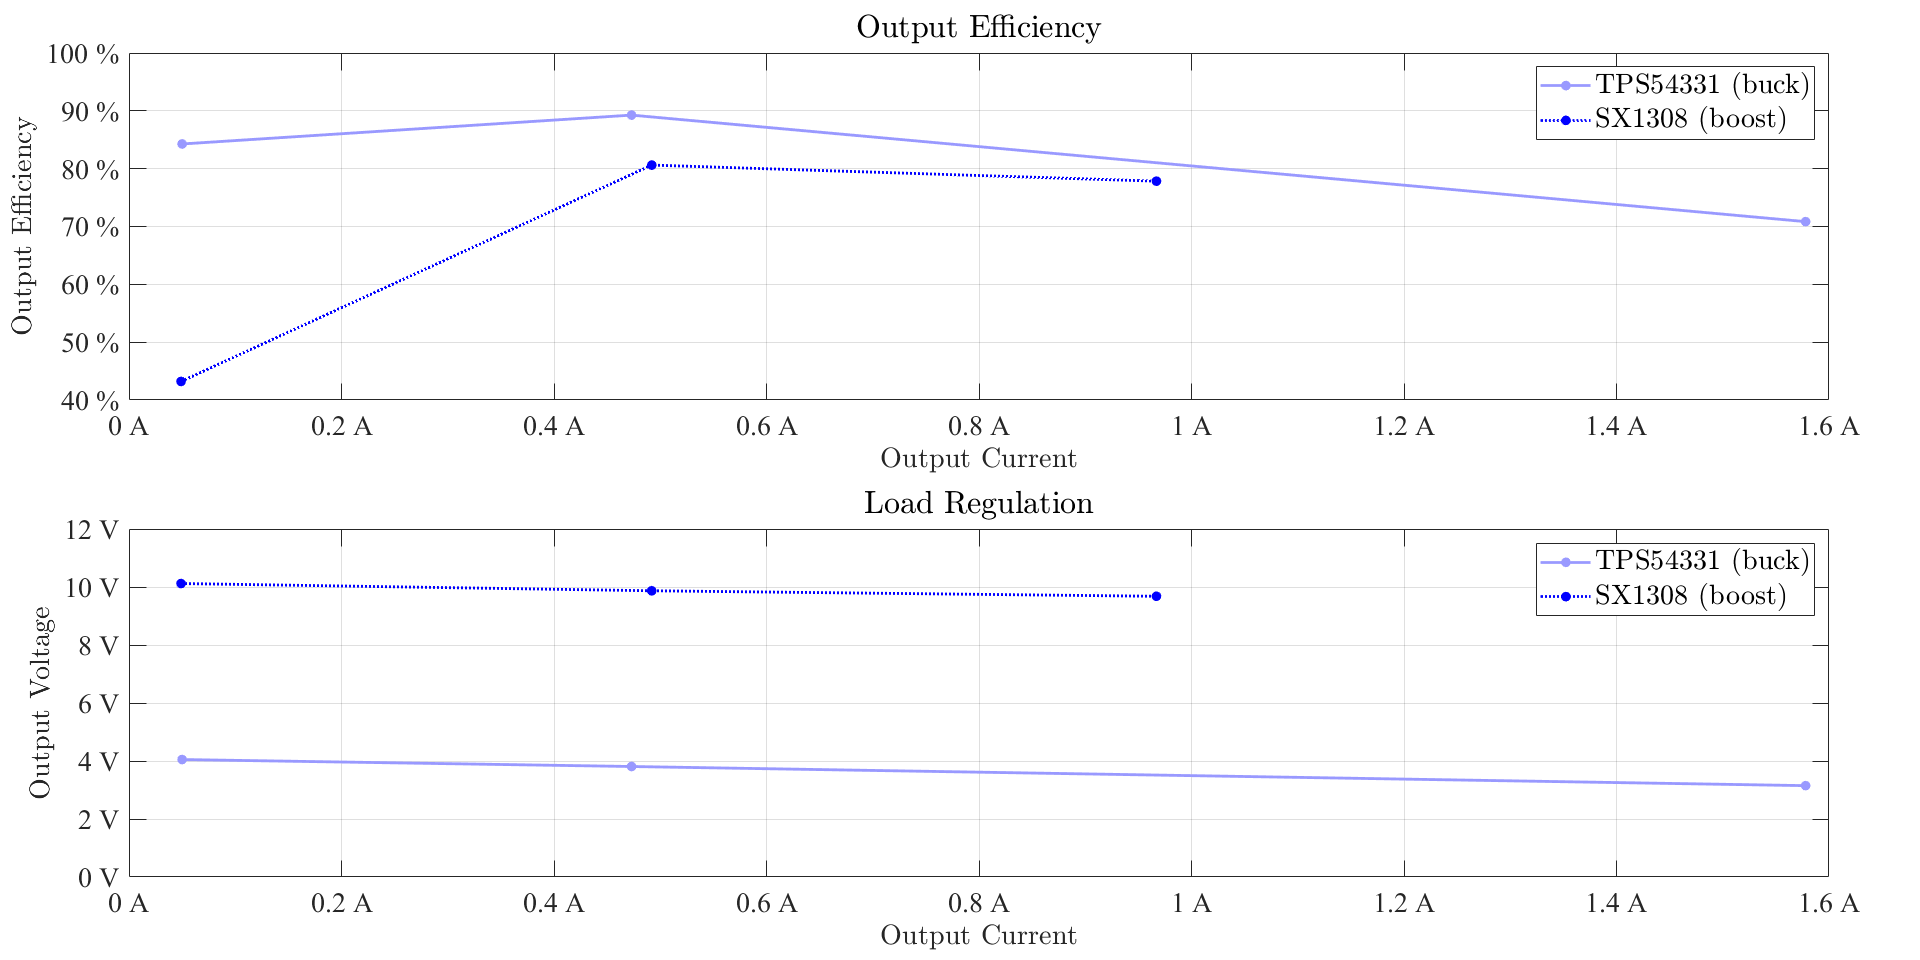

%stc = MyPlot([data1(:, 2)'; data1(:, 2)'], [efficiency(1:3)'; efficiency(4:6)']);

stc = MyPlot_2window([data(1:3, 4)'; data(4:6, 4)'], [efficiency(1:3)'; efficiency(4:6)'], [data(1:3, 4)'; data(4:6, 4)'], [data(1:3, 3)'; data(4:6, 3)'], 0);

MyFigure_ChangeSize([2 1]*512*1.5)
stc.ax1.XLim = [0 1.6];
stc.ax1.YLim = [40 100];
stc.ax2.XLim = [0 1.6];
stc.ax2.YLim = [0 12];
stc.ax1.XTickLabel = stc.ax1.XTickLabel + " A";
stc.ax2.XTickLabel = stc.ax2.XTickLabel + " A";
stc.ax1.YTickLabel = stc.ax1.YTickLabel + " %";
stc.ax2.YTickLabel = stc.ax2.YTickLabel + " V";
stc.plot1.label.x.String = 'Output Current';
stc.plot1.label.y.String = 'Output Efficiency';
stc.plot2.label.x.String = 'Output Current';
stc.plot2.label.y.String = 'Output Voltage';
stc.plot1.axes.Title.String = 'Output Efficiency';
stc.plot2.axes.Title.String = 'Load Regulation';
stc.plot1.leg.String = ["TPS54331 (buck)", "SX1308 (boost)"];
stc.plot2.leg.String = ["TPS54331 (buck)", "SX1308 (boost)"];
stc.plot1.leg.Location = 'northeast';
stc.plot2.leg.Location = 'northeast';

stc.fig.WindowStyle = 'modal';

%MyExport_pdf

%stc = MyPlot_2window(data1(:, 2), efficiency(1:3), data2(:, 2), efficiency(4:6), 0);